clear all;

## Onset Conditions

dimension:

N=20;
% correlation paramter:
eta=1.;
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=1000;
% Delta t:
Dt=0.5;
% Temperature: Increase it!!!
T=0.1;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

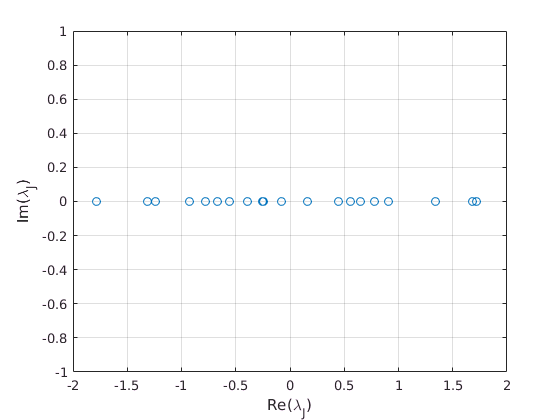

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')
hold on;

## run multiple time steps

T=0.001

T = 1.0000e-03

%time steps are generated as Dt*2^-i for i \in {2,.. 14}
for i=1:14
    [C,m(i),s(i)]=step(Dt/(2^i),x,J,N,T,tot_time);
%plot(2+Dt:Dt:tot_time,C(find(mask>2)))% if you want to plot, wait for
%stationarity after 2
end
save('correlation_timestep')

## run multiple Temperatures

%time steps are generated as Dt*2^-i for i \in {2,.. 14}
T=0.5;
dt=Dt/(2^6);
for i=1:14
    [C,m(i),s(i)]=step(Dt/(2^6),x,J,N,T/(2^i),tot_time);
%plot(2+Dt:Dt:tot_time,C(find(mask>2)))% if you want to plot, wait for
%stationarity after 2
end
save('correlation_T')

## Plotting

Show correlation with respect to 

- time step

- temperature

## Correlation wrt time step

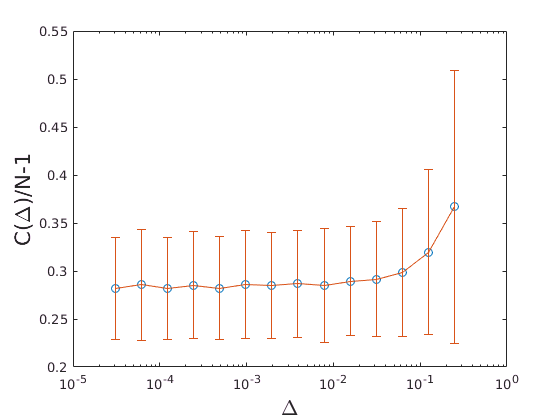

load correlation_timestep.mat

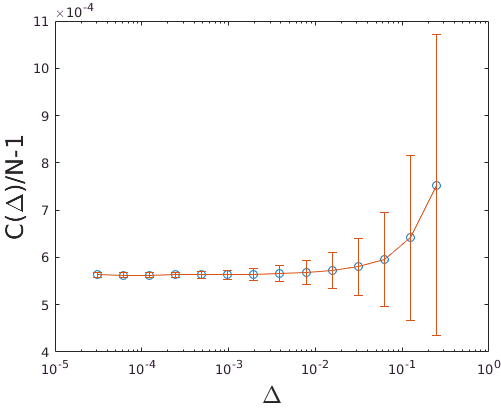


dt=Dt./2.^(1:14);
semilogx(dt,m/N-1,'o')
hold on
errorbar(dt,m/N-1,s/N)
xlabel('\Delta','Fontsize',18)
ylabel('C(\Delta)/N-1','Fontsize',18)
%xt = get(gca, 'XTick');
%set(gca, 'FontSize', 14)

hold off
fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 5 5];
fig=tightfig(fig);
print('time-step', '-dpng', '-r300');

## Correlation wrt temperatures

load correlation_T.mat

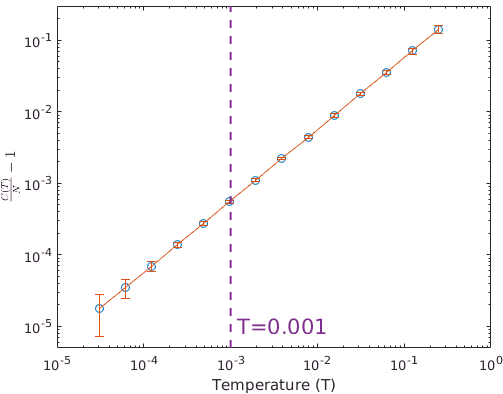

figure()
Ts=T./(2.^(1:14));
loglog(Ts,m/N-1,'o')
hold on
errorbar(Ts,m/N-1,s/N)
xlabel('Temperature (T)','Fontsize',18)
ylabel('$\frac{C(T)}{N}-1$','Interpreter','latex','Fontsize',18)
line([0.001,0.001],ylim(),'LineStyle','--','LineWidth',1.5,'Color',	[0.4940, 0.1840, 0.5560])
ylim([0.000005,0.3]);
text(0.0012,0.00001,'T=0.001','Color',	[0.4940, 0.1840, 0.5560],'FontSize',16)
xt = get(gca, 'XTick');
set(gca, 'FontSize', 10)
fig = gcf;
fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 5 5];
fig=tightfig(fig);
print('T', '-dpng', '-r300');
hold off